Helper Function

function T = TranslationTransformation(F, dx, dy, dz)
    Translate = [ 1 0 0 dx;
                  0 1 0 dy;
                  0 0 1 dz;
                  0 0 0 1];
    T = Translate * F;

end

function T = RotationTransformation(F, axis, angle)
    if ismember(axis, ["x", "n"])
        Rotation = [ 1      0          0      0;
                     0 cos(angle) -sin(angle) 0;
                     0 sin(angle) cos(angle)  0;
                     0      0         0       1];
    elseif ismember(axis, ["y", "o"])
        Rotation = [ cos(angle) 0 sin(angle) 0;
                     0          1     0      0;
                    -sin(angle) 0 cos(angle) 0;
                     0          0     0      1];
    elseif ismember(axis, ["z", "a"])
        Rotation = [ cos(angle) -sin(angle) 0 0;
                     sin(angle) cos(angle)  0 0;
                         0          0       1 0 ;
                         0          0       0 1];
    else
        Rotation = [0 0 0 0;
                    0 0 0 0;
                    0 0 0 0;
                    0 0 0 0;];
    end
    if ismember(axis, ["x", "y", "z"])
        T = Rotation * F;
    elseif ismember(axis, ["n", "o", "a"])
        T = F * Rotation;
    else
        T = [0 0 0 0;
             0 0 0 0;
             0 0 0 0;
             0 0 0 0;];
    end


end

# Problem 1

P_B = [0 -3 1 1]';

T_AB = [-0.5      0  sqrt(3)/2   -1;
      sqrt(3)/2   0     0.5      -2;
         0        1      0        1;
         0        0      0        1];

% Part 1
P_A = T_AB * P_B

P_A =    -0.1340
   -1.5000
   -2.0000
    1.0000



% Part 2
F = [1 0 0 0;
     0 1 0 0;
     0 0 1 0;
     0 0 0 1;];
T_1 = TranslationTransformation(F, 2, 0, 1)

T_1 =      1     0     0     2
     0     1     0     0
     0     0     1     1
     0     0     0     1


T_2 = RotationTransformation(   F, 'y', -pi/2)

T_2 =     0.0000         0   -1.0000         0
         0    1.0000         0         0
    1.0000         0    0.0000         0
         0         0         0    1.0000


T_3 = TranslationTransformation(F, 1, 2, 3)

T_3 =      1     0     0     1
     0     1     0     2
     0     0     1     3
     0     0     0     1


T_4 = RotationTransformation(   F, 'x', pi/2)

T_4 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000



T_14 = T_4*T_3*T_2*T_1

T_14 =     0.0000         0   -1.0000    0.0000
   -1.0000    0.0000   -0.0000   -5.0000
    0.0000    1.0000    0.0000    2.0000
         0         0         0    1.0000



P_A_new = T_14*P_A

P_A_new =     2.0000
   -4.8660
    0.5000
    1.0000



P_B_new = T_14*P_B

P_B_new =    -1.0000
   -5.0000
   -1.0000
    1.0000




P_B_frame = [1 0 0  0;
             0 1 0 -3;
             0 0 1  1;
             0 0 0  1;];
hold on
view([130,30])
xlim([-3,3])
ylim([-3,3])
zlim([-3,3])
grid on
grid minor
Fnoa = T_14*P_B_frame

Fnoa =     0.0000         0   -1.0000   -1.0000
   -1.0000    0.0000   -0.0000   -5.0000
    0.0000    1.0000    0.0000   -1.0000
         0         0         0    1.0000


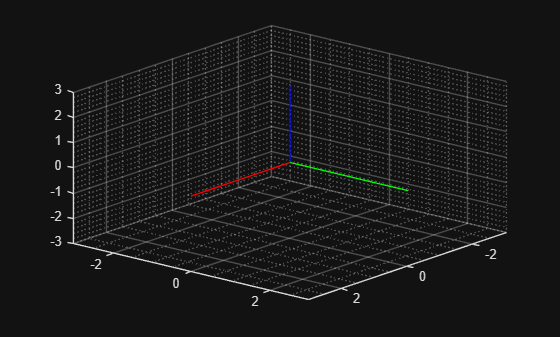

% X-Axis
quiver3(0,0,0,5,0,0, LineWidth=1,Color= "red")
% Y-Axis
quiver3(0,0,0,0,5,0, LineWidth=1,Color= "green" )
% Z-Axis
quiver3(0,0,0,0,0,5, LineWidth=1,Color= "blue" )

% N-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),Fnoa(1,1)*2,Fnoa(2,1)*2,Fnoa(3,1)*2, LineWidth=2,Color= "red" )
% O-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),Fnoa(1,2)*2,Fnoa(2,2)*2,Fnoa(3,2)*2, LineWidth=2,Color= "green" )
% A-Axis
quiver3(Fnoa(1,4),Fnoa(2,4),Fnoa(3,4),Fnoa(1,3)*2,Fnoa(2,3)*2,Fnoa(3,3)*2, LineWidth=2,Color= "blue" )
hold off


F = P_B_frame

F =      1     0     0     0
     0     1     0    -3
     0     0     1     1
     0     0     0     1


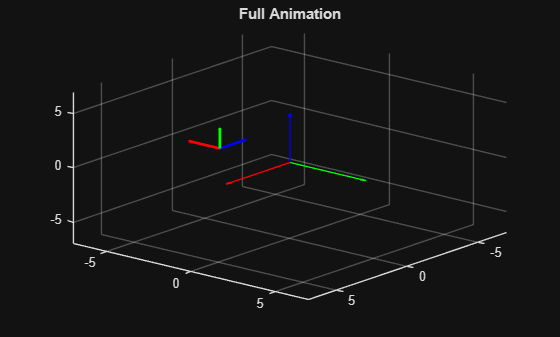

x = 1;
graph_step = 30;
steps = 4;
Step_Size = graph_step * steps;
for i = 1:1:Step_Size
    cla
    if i == 1
        fig = figure(1);
        grid on
        grid minor
        view([130,30])
        xlim([-7,7])
        ylim([-7,7])
        zlim([-7,7])
        title('Full Animation');
    end
    hold on
    if i <= graph_step
        index = i * 1/graph_step;
        F_loop = TranslationTransformation(F, 2* index, 0* index, 1* index);
        if i == graph_step
            F = F_loop;
        end

    elseif i <= graph_step *2 
        index = (i-graph_step) * 1/graph_step;
        F_loop = RotationTransformation(   F, 'y', -pi/2* index);
        if i == graph_step *2
            F = F_loop;
        end

    elseif i <= graph_step *3 
        index = (i-graph_step*2) * 1/graph_step;
        F_loop =TranslationTransformation(F, 1* index, 2* index, 3* index);
        if i == graph_step*3
            F = F_loop;
        end
    elseif i <= graph_step *4 
        index = (i-graph_step*3) * 1/graph_step;
        F_loop = RotationTransformation(   F, 'x', pi/2 * index);
        if i == graph_step*4
            F = F_loop;
        end
    else

    end


    % X-Axis
    quiver3(0,0,0,5,0,0, LineWidth=1,Color= "red")
    % Y-Axis
    quiver3(0,0,0,0,5,0, LineWidth=1,Color= "green" )
    % Z-Axis
    quiver3(0,0,0,0,0,5, LineWidth=1,Color= "blue" )
    
    % X-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,1)*2,F_loop(2,1)*2,F_loop(3,1)*2, LineWidth=2,Color= "red" )
    % Y-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,2)*2,F_loop(2,2)*2,F_loop(3,2)*2, LineWidth=2,Color= "green" )
    % Z-Axis
    quiver3(F_loop(1,4),F_loop(2,4),F_loop(3,4),F_loop(1,3)*2,F_loop(2,3)*2,F_loop(3,3)*2, LineWidth=2,Color= "blue" )
    hold off


    drawnow ('limitrate'); 
    frame = getframe(fig);
    im{x} = frame2im(frame);
    x = x + 1;
end

# Problem 2

clc;
clear;
syms theta d alpha a
syms theta_1 theta_2 theta_3

L1 = 0.3

L1 = 0.3000

L2 = 0.25

L2 = 0.2500

L3 = 0.1

L3 = 0.1000


T = [ cos(theta) -sin(theta)*cos(alpha)  sin(theta)*sin(alpha) a*cos(theta);
      sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
          0             sin(alpha)            cos(alpha)            d;
          0                 0                     0                 1];

T01 = subs(T, [theta, d, a, alpha], [theta_1  0  L1   0]);
T12 = subs(T, [theta, d, a, alpha], [theta_2  0  L2   0]);
T2E = subs(T, [theta, d, a, alpha], [theta_3  0  L3   0]);


T0E = T01 * T12 * T2E ;
T0E = simplify(T0E)

$$T0E = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & -\sigma_{1} & 0 & \frac{\sigma_{2}}{10}+\frac{\cos\left(\theta_{1}+\theta_{2}\right)}{4}+\frac{3\,\cos\left(\theta_{1}\right)}{10}\\ \sigma_{1} & \sigma_{2} & 0 & \frac{\sigma_{1}}{10}+\frac{\sin\left(\theta_{1}+\theta_{2}\right)}{4}+\frac{3\,\sin\left(\theta_{1}\right)}{10}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right) \end{array}$$

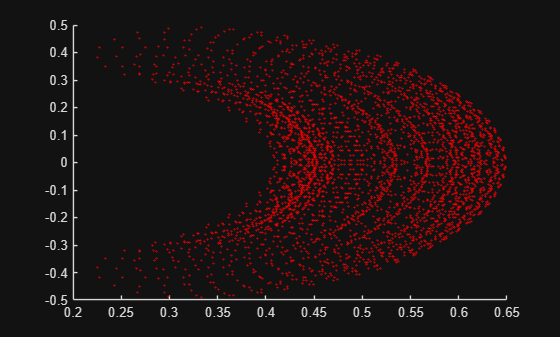


theta_1_range = deg2rad(-30:6:30);
theta_2_range = deg2rad(-45:5:45);
theta_3_range = deg2rad(-170:20:170);
figure 
hold on
for angle_1 = theta_1_range
    for angle_2 = theta_2_range
        for angle_3 = theta_3_range
            temp = subs(T0E, [theta_1, theta_2, theta_3], [angle_1  angle_2  angle_3]);
            plot(temp(1,4),temp(2,4), 'o','MarkerSize',1,'MarkerEdgeColor','red')
        end
    end
end
hold off

# Problem 3

%Part 2
clc;
clear;
syms theta d alpha a
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6


T = [ cos(theta) -sin(theta)*cos(alpha)  sin(theta)*sin(alpha) a*cos(theta);
      sin(theta)  cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);
          0             sin(alpha)            cos(alpha)            d;
          0                 0                     0                 1];

TU0 = [ 1   0   0   0;
        0   1   0   0;
        0   0   1   675;
        0   0   0   1];
T01 = subs(T, [theta, d, a, alpha], [theta_1       0    260   pi/2]);
T12 = subs(T, [theta, d, a, alpha], [theta_2+pi/2  0    680     0]);
T23 = subs(T, [theta, d, a, alpha], [theta_3       0     0    pi/2]);
T34 = subs(T, [theta, d, a, alpha], [theta_4      670   -35  -pi/2]);
T45 = subs(T, [theta, d, a, alpha], [theta_5       0     0    pi/2]);
T5E = subs(T, [theta, d, a, alpha], [theta_6      115    0      0]);

TUE = TU0 * T01 * T12 * T23 * T34 * T45 * T5E;
%Part 3
TUE = simplify(TUE)

%Part 4
T5E_0 = subs(TUE, [theta_1, theta_2, theta_3, theta_4, theta_5, theta_6], [0 0 0 0 0 0])

$$T5E\_0 = \left(\begin{array}{cccc} 0 & 0 & 1 & 1045\\ 0 & -1 & 0 & 0\\ 1 & 0 & 0 & 1320\\ 0 & 0 & 0 & 1 \end{array}\right)$$

%Part 5
T5E_1 = subs(TUE, [theta_1, theta_2, theta_3, theta_4, theta_5, theta_6], [pi/6 pi/4 -pi/4 pi/3 0 0])

$$T5E\_1 = \left(\begin{array}{cccc} \frac{\sqrt{3}}{4} & \frac{1}{4} & \frac{\sqrt{3}}{2} & \frac{2055\,\sqrt{3}}{4}-170\,\sqrt{2}\,\sqrt{3}\\ -\frac{3}{4} & -\frac{\sqrt{3}}{4} & \frac{1}{2} & \frac{2195}{4}-170\,\sqrt{2}\\ \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0 & 340\,\sqrt{2}+\frac{1315}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

# Problem 4

clc;
clear;
T_H1_P =[ 1   0   0   0;
          0   0  -1   1;
          0   1   0   0;
          0   0   0   1];

T_H2_T =[0.5      0   sqrt(3)/2  2;
          0       1       0     -1;
      -sqrt(3)/2  0      0.5     0;
          0       0       0      1];

T_C_B1 =[ 1   0   0   2;
          0   1   0   2;
          0   0   1   4;
          0   0   0   1];

T_C_B2 =[ 1   0   0  -4;
          0   1   0   1;
          0   0   1   4;
          0   0   0   1];

%Part 1
T_C_P =[ 1   0   0   0;
         0   1   0   0;
         0   0   1   2;
         0   0   0   1];

T_B1_H1 = (T_H1_P * T_C_P^-1 * T_C_B1)^-1

T_B1_H1 =      1     0     0    -2
     0     0     1    -2
     0    -1     0    -1
     0     0     0     1



%Part 2
T_T_P =[ -0.30   0.37   -0.89   -2;
          0.60   0.74    0.11   -2;
          0.75  -0.56   -0.44    3;
            0      0       0     1];

T_B2_H2 = (T_H2_T * T_T_P * T_C_P^-1 * T_C_B2)^-1

T_B2_H2 =     0.4734    0.6609    0.5781    2.4111
   -0.2605    0.7992   -0.5504    4.1137
   -0.8297    0.1095    0.5494   -0.4621
         0         0         0    1.0000
